# Adds a CV Pipe in a network.

## This example contains: 

- Load a network. 

- Plot network components. 

- Get from and to nodes for add cv pipe. 

- Plot new network with changes. 

- Unload library.

## Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.
EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.


ans = int32
   11


EPANET Class is unloaded


## Load a network.

d = epanet('Net1.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Net1.inp"...
Input File "Net1.inp" loaded successfully.



disp('Add a CV pipe')

Add a CV pipe


## Plot network components.

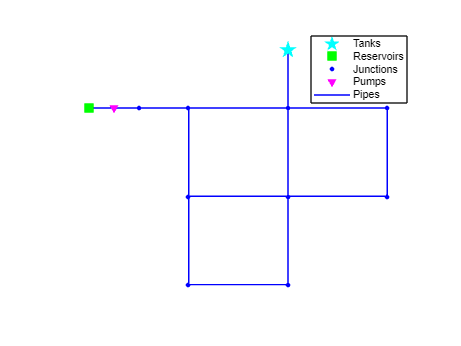

d.plot;

## Get from and to nodes for add cv pipe.

fromNode = d.getNodeNameID{2};
toNode = d.getNodeNameID{6};
node_index = d.addLinkPipeCV('CVPipe',fromNode,toNode);

## Plot new network with changes.

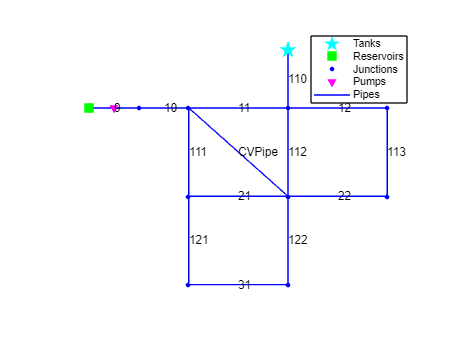

d.plot('links','yes');

## Unload library.

d.unload

EPANET Class is unloaded
